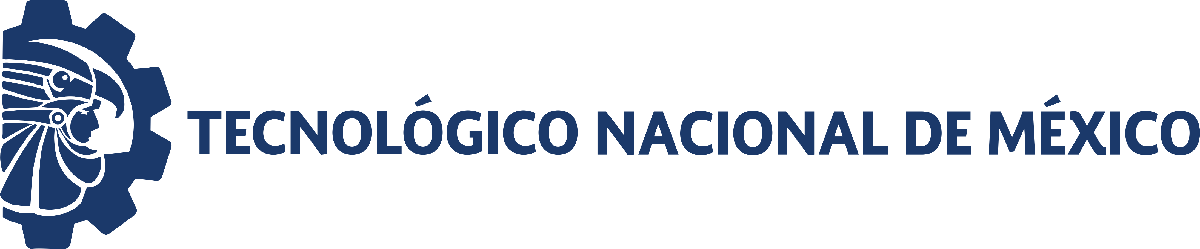                                 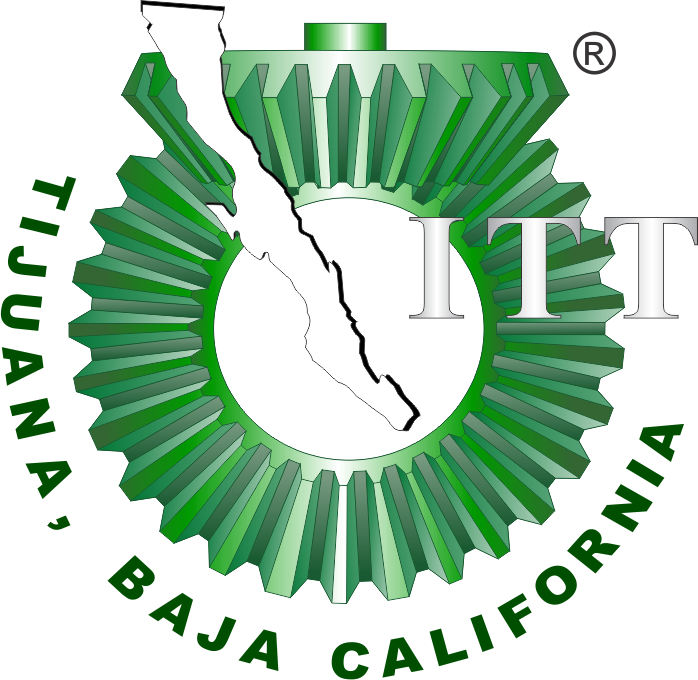

# Práctica 4: Regeneracion de globulos rojos 

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general           

##           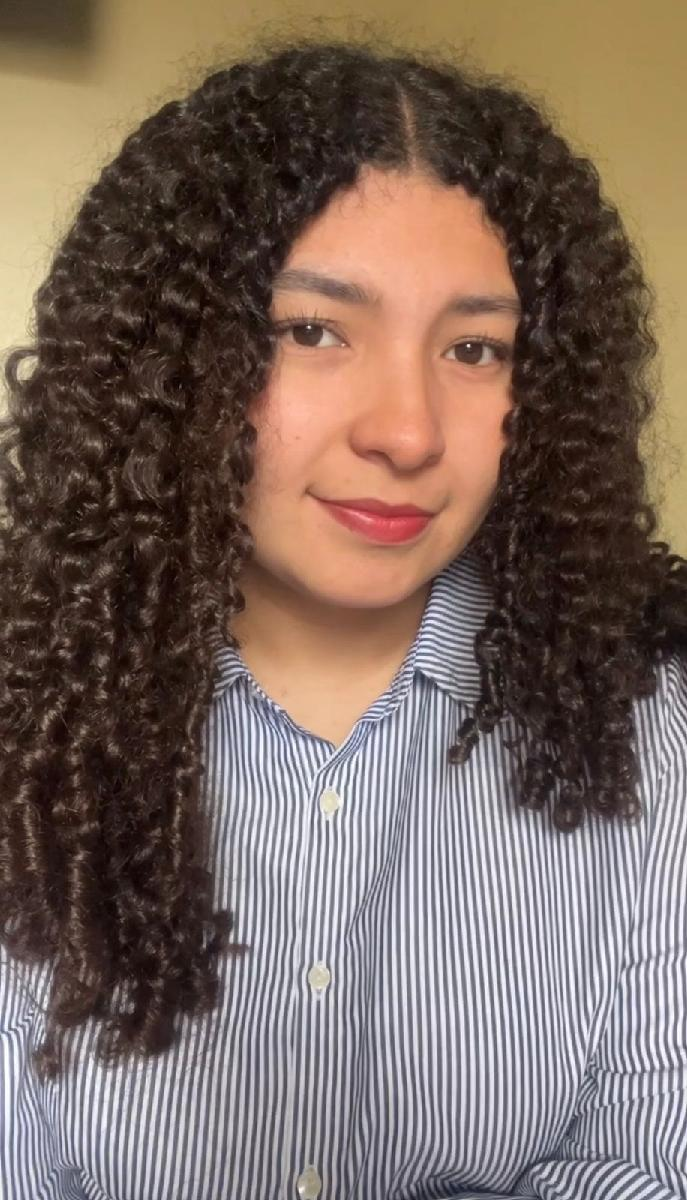

Nombre del alumno: Johana Jazmin De La Torre Gomez

Número de control: 22211751

Correo institucional: l22211751**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; format short; warning('off','all')
tend = 180; %tiempo de simulacion en dias 
dt = 1E-3; %intervalo de integracion para el metodo de solucion por diferentes finitos 
n = round(tend/dt); %Cantidad de iteracion para el metodo numerico 

%Condiciones iniciales base para cada paciente 
x1_0 = 59; x2_0 = 44; x3_0 = 885;

%Parametros particulares para cada paciente 
gamma = [0.769; 0.388; 0.510; 0.590; 0.262; 0.324; 0.356; 0.089; 0.243; 0.057];
beta = [1.650; 0.867; 1.617; 2.615; 1.518; 2.676; 0.891; 2.557; 0.925; 0.879];

seed = 22211751; %semilla para asegurar reproductibilidad 
rng(seed, 'twister')
%Intervalo de las condiciones iniciales 
xmin = 0.99; xmax = 1.01;
interval = xmin + (xmax - xmin).*rand(numel(gamma),1);

%Condiciones iniciales para cada paciente
x1_0 = x1_0*interval; disp('x1(0) = '); disp(x1_0');...
x2_0 = x2_0*interval; disp('x2(0) = '); disp(x2_0');...
x3_0 = x3_0*interval; disp('x3(0) = '); disp(x3_0');

x1(0) = 
   58.9165   58.5547   58.8964   58.7746   58.7569   59.3640   59.2786   58.9809   58.4399   58.5420



x2(0) = 
   43.9378   43.6679   43.9227   43.8319   43.8187   44.2715   44.2078   43.9858   43.5823   43.6584



x3(0) = 
  883.7480  878.3208  883.4454  881.6183  881.3528  890.4600  889.1792  884.7139  876.5987  878.1295



## Caso: Sin transfusion sanguinea [u(t) = 0]

u = zeros(n+1,1); %No hay transfusion
fig = 1;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Caso: Con transfusion sanguinea 

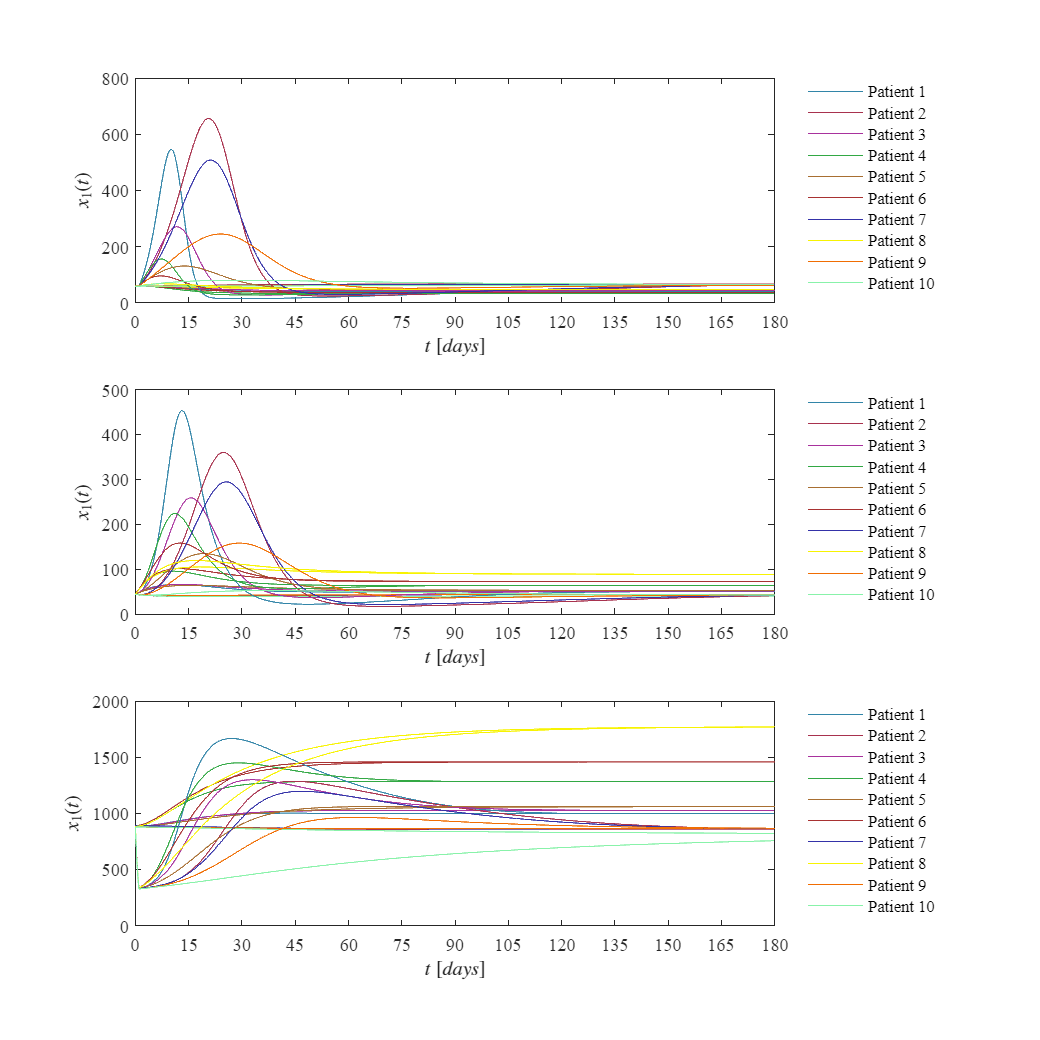

u = zeros(n+1,1); %No hay transfusion
for k = 1:1000
    if t(k) <= 1 
         u(k) = 1; 
    else
        u(k) = 0; 
    end
end 
fig = 2;
for i = 1:10
    [t,x1,x2,x3] = system(x1_0(i),x2_0(i),x3_0(i),beta(i),gamma(i),u,dt,tend);
    plotdata(t,x1,x2,x3,fig)
end

## Funcion: Modelo matematico


$$\overset{\ldotp }{x_1 } =\beta \left(x_0 -k_{1\left(\right.} \left(x_1 \right)+\frac{\gamma \left(B_{\textrm{ase}} -x_3 \right)\left(1-u\left(t\right)x_1 \right)}{B_{\textrm{ase}} }\right)$$



$$\overset{\ldotp }{x_2 } =\beta \left(k_1 x_1 -k_2 x_2 \right)$$



$$\overset{\ldotp }{x_3 } =\beta \left(k_2 x_{2\;} -{\mathrm{ax}}_3 \right)-u\left(t\right)x_3$$



function [t,x1,x2,x3] = system(x1_0,x2_0,x3_0, beta,gamma,u,dt,tend)
%Parametros fijos para el sistema
Base = 885.42; x0 = 7.3785; k1 = 0.125; k2 = 0.1667; alpha = 0.00833;
t = (0:dt:tend);
n = round(tend/dt);
x1 = zeros(n+1,1); x1(1) = x1_0;
x2 = zeros(n+1,1); x2(1) = x2_0;
x3 = zeros(n+1,1); x3(1) = x3_0;

    for i = 1:n
        x1(i+1) = x1(i) + (beta*(x0 - k1*x1(i)) + gamma*(Base - x3(i))*(1 - u(i))*x1(i)/Base)*dt;
        x2(i+1) = x2(i) + (beta*k1*x1(i) - k2*x2(i))*dt;
        x3(i+1) = x3(i) + (beta*(k2*x2(i) -  alpha*x3(i)) - u(i)*x3(i))*dt;
    end
end 


## Funcion: Soluciones de tiempo 

function plotdata(t,x1,x2,x3,fig)
set(figure(fig),'Color','w')
set(gcf,'Units','Centimeters','Position',[1,1,20,20])
    mycolors = [50, 133, 168;
        168, 50, 78;
        168, 50, 157;
        50, 168, 68;
        168, 111, 50;
        168, 50, 50;
        52, 50, 168;
        247, 243, 2;
        240, 109, 2;
        136, 242, 169]/255;

subplot(3,1,1)
hold on; grid off; box on;colororder(mycolors)
plot(t,x1)
xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
ylabel ('$x_1(t)$','Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)
L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca,'FontName','Times New Roman','FontSize',10) 

subplot(3,1,2)
hold on; grid off; box on;colororder(mycolors)
plot(t,x2)
xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
ylabel ('$x_1(t)$','Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)
L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca,'FontName','Times New Roman','FontSize',10)

subplot(3,1,3)
hold on; grid off; box on;colororder(mycolors)
plot(t,x3)
xlabel('$t$ $[days]$','Interpreter','latex','FontSize',10)
ylabel ('$x_1(t)$','Interpreter','latex','FontSize',10)
xlim([0 180]); xticks(0:15:180)
L= legend('Patient 1','Patient 2','Patient 3','Patient 4','Patient 5','Patient 6','Patient 7','Patient 8','Patient 9','Patient 10');
set(L,'FontSize',9,'Box','Off','Location','NorthEastOutside');
set(gca,'FontName','Times New Roman','FontSize',10)


    if fig ==1
        exportgraphics(gcf,['Caso sin transfusion.pdf'],'ContentType','vector')
    elseif fig ==2
        exportgraphics(gcf,['Caso con Transfusion.pdf'],'ContentType','vector')
    end
end